# Create a Happy New Year text video

## Clear variables and figures

clear variables;
clf;

## Set the texts and their font type and size

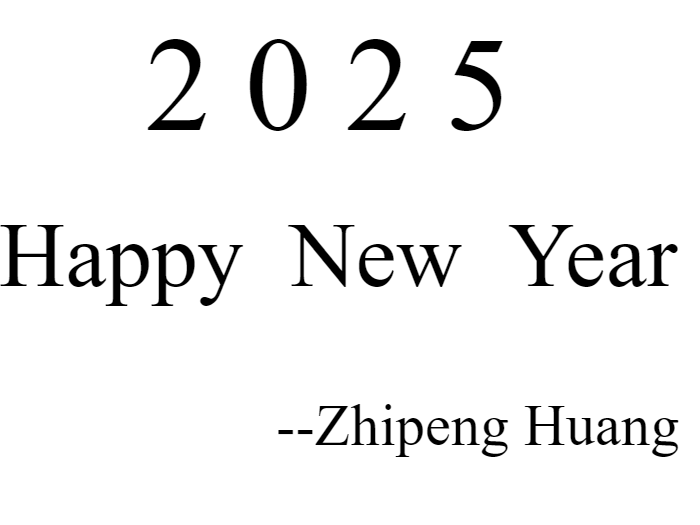

h1 = figure;
axis off;
text(0.1,0.9,"2 0 2 5","FontSize",80,"FontName","Times New Roman");
text(-0.17,0.5,"Happy  New  Year","FontSize",55,"FontName","Times New Roman");
text(0.34,0.1,"--Zhipeng Huang","FontSize",35,"FontName","Times New Roman");

## Save the text as an image

saveas(gcf,'temp.jpg')

## Read the image and decrease the pixel size 

im = imread('temp.jpg');
BW = rgb2gray(im);
BW = imresize(BW,0.3); % 0.3 is the decrease ratio and adjustable

BW(BW>100) = 255;
BW(BW<=100) = 0;

## Crop the image

[a,b] = find(BW==0);
BW(max(a):end,:) = [];
BW(1:min(a),:) = [];
BW(:,max(b):end) = [];
BW(:,1:min(b)) = [];

## Create the animation and save it to a mp4 file

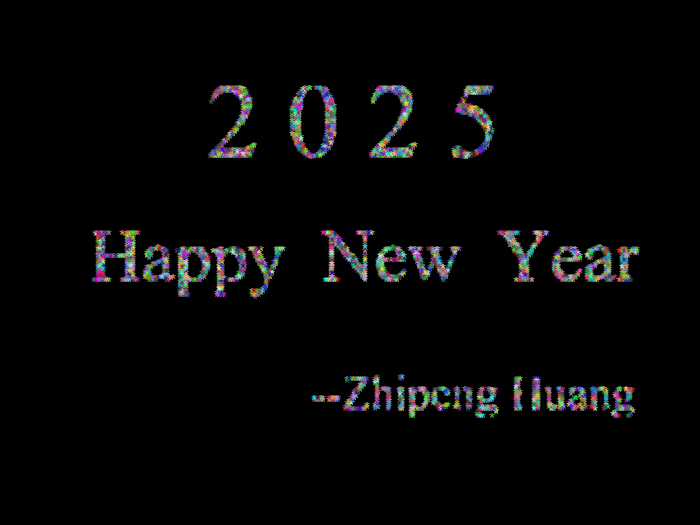

v = VideoWriter('new_year_animation','MPEG-4');
v.FrameRate = 160;
open(v);
f=figure;set(gcf, 'Color', [0 0 0]);
axis off
axis equal
axis([1 size(BW,2) 1 size(BW,1)])
hold on;set(gca, 'color', [0 0 0]);
for i=shufflenum(1:numel(BW))
    [row, col] = ind2sub(size(BW), i); % Convert linear index to row and column indices
    if BW(row,col)==0
        text(col,size(BW,1)-row,'*','Color',rand(1,3),'FontSize',10); 
        pause(0.001)
        frame = getframe(gcf);
        writeVideo(v,frame);
    end
end

close(v);


## Create the shuffel function which is called before

function nv=shufflenum(nv)
   nv=nv(randperm(length(nv)));
end